% Author: Anna Bosc
% Affiliation 1: Istituto Italiano di Tecnologia
% Affiliation 2: Politecnico di Milano
% Year: 2026
% Description: MATLAB code for trajectory analysis of Chlamydomonas motility
% Associated publication: Manuscript under review
% DOI: (to be added upon publication)
% 
% % License: MIT License
% This code is distributed under the terms of the MIT License.
% See LICENSE file for details.

% PARAMETERS
clear all;
close all;
java.lang.System.gc

frame_intervals = 20;

main_folder =''; %path main_folder
% --- Definition of flash: intervals [start_frame, end_frame] ---
flash_intervals_frames = [
   100, 100;
    % add others if it is necessary
];

% sample folders
sample_folders = dir(fullfile(main_folder, '*')); %name subfolders here
sample_folders = sample_folders([sample_folders.isdir]); % directories only
for i = 1:length(sample_folders)
    sample_path = fullfile(main_folder, sample_folders(i).name);

    % subfolders "video*"
    video_folders = dir(fullfile(sample_path, '*')); %name subsubfolders here
    video_folders = video_folders([video_folders.isdir]); % directories only

    for j = 1:length(video_folders)
        video_path = fullfile(sample_path, video_folders(j).name);

          %memory cleaning
    close all;                    
    clearvars -except main_folder frame_intervals flash_intervals_frames ...
                      sample_folders sample_path video_folders video_path j i;
    %variable reset
    msd_curve_all = [];
    boxplot_data  = [];
    % -----------------------------------------
               
% file name (*_save)
file_struct = dir(fullfile(video_path, '*converted_data.mat')); 
%file_struct = dir(fullfile(video_path, 'Untitledsave.xml'));

if ~isempty(file_struct)
    file_name = file_struct.name; % Took the first
    file_path = fullfile(video_path, file_struct(1).name);
    msd_path = fullfile(video_path, 'MSD_global');
if ~exist(msd_path, 'dir')
    mkdir(msd_path);   
end


% Upload data
dataStruct = load(file_path);
converted_data = dataStruct.converted_data;
max_frames = max(converted_data.FRAME_SOURCE);
num_intervals = floor(max_frames / frame_intervals);

msd_evolutions = cell(1, num_intervals);
msd_std_evolutions = cell(1, num_intervals);
msd_mean_per_interval = NaN(1, num_intervals);
msd_std_per_interval = NaN(1, num_intervals);
msd_per_alga_all = cell(1, num_intervals);

for interval_index = 1:num_intervals
    % interval definition
    start_frame = (interval_index - 1) * frame_intervals + 1;
    end_frame = start_frame + frame_intervals - 1;
    interval_frames = start_frame:end_frame;

   
    algae_in_interval = converted_data(ismember(converted_data.FRAME_SOURCE, interval_frames), :);
    [track_ids, ~, group_indices] = unique(algae_in_interval.TRACK_ID);
    frame_counts = accumarray(group_indices, 1);

    % only valid tracks
    valid_tracks = track_ids(frame_counts == frame_intervals);

    algae_in_interval = algae_in_interval(ismember(algae_in_interval.TRACK_ID, valid_tracks), :);

    % Debug
    fprintf('interval %d: %d valid tracks\n', interval_index, length(valid_tracks));
    if isempty(valid_tracks)
        continue;
    end

    % Time to seconds
flash_intervals_times = nan(size(flash_intervals_frames));
for ff = 1:size(flash_intervals_frames,1)
    idx_start = find(converted_data.FRAME_SOURCE == flash_intervals_frames(ff,1), 1, 'first');
    idx_end   = find(converted_data.FRAME_SOURCE == flash_intervals_frames(ff,2), 1, 'first');
    if ~isempty(idx_start)
        flash_intervals_times(ff,1) = converted_data.POSITION_T_SOURCE(idx_start);
    end
    if ~isempty(idx_end)
        flash_intervals_times(ff,2) = converted_data.POSITION_T_SOURCE(idx_end);
    end
end

 % MSD per algae
unique_tracks = unique(algae_in_interval.TRACK_ID);
msd_per_alga = NaN(length(unique_tracks), frame_intervals);

for i = 1:length(unique_tracks)
    track_id = unique_tracks(i);
    track_data = algae_in_interval(algae_in_interval.TRACK_ID == track_id, :);
    track_data = sortrows(track_data, 'FRAME_SOURCE');
    x0 = track_data.POSITION_X_SOURCE(1);
    y0 = track_data.POSITION_Y_SOURCE(1);
    msd_per_alga(i,:) = (track_data.POSITION_X_SOURCE - x0).^2 + (track_data.POSITION_Y_SOURCE - y0).^2;
end

msd_per_alga_all{interval_index} = msd_per_alga; 

    msd_mean_per_frame = mean(msd_per_alga, 1, 'omitnan');
    msd_std_per_frame = std(msd_per_alga, 0, 1, 'omitnan');
    msd_se_per_frame = msd_std_per_frame ./ sqrt(sum(~isnan(msd_per_alga), 1));

    
    msd_evolutions{interval_index} = msd_mean_per_frame;
    msd_std_evolutions{interval_index} = msd_std_per_frame;
    msd_mean_per_interval(interval_index) = mean(msd_mean_per_frame, 'omitnan');
    msd_std_per_interval(interval_index) = std(msd_mean_per_frame, 'omitnan');

    % CSV saving
    % 
    frames = (1:frame_intervals)';
    msd_mean = msd_mean_per_frame';
    msd_std = msd_std_per_frame';
    msd_se = msd_se_per_frame';
    
    
    if length(frames) == length(msd_mean) && length(msd_mean) == length(msd_std) && length(msd_std) == length(msd_se)
        
        interval_table = table(frames, msd_mean, msd_std, msd_se, ...
            'VariableNames', {'Frame', 'MSD_Mean', 'MSD_Std', 'MSD_SE'});
        file_name = 'msd_evolution_intervals.xlsx';  
        sheet_name = sprintf('Interval_%d', interval_index);  
        writetable(interval_table, fullfile(msd_path, file_name), 'Sheet', sheet_name);
    else
        warning('The columns have different lengths for the %d range', interval_index);
    end
end

interval 1: 13 valid tracks
interval 2: 10 valid tracks
interval 3: 10 valid tracks
interval 4: 9 valid tracks
interval 5: 11 valid tracks
interval 6: 7 valid tracks
interval 7: 9 valid tracks
interval 8: 10 valid tracks
interval 9: 10 valid tracks
interval 10: 8 valid tracks
interval 11: 11 valid tracks
interval 12: 9 valid tracks
interval 13: 8 valid tracks
interval 14: 5 valid tracks
interval 15: 7 valid tracks
interval 16: 7 valid tracks
interval 17: 10 valid tracks
interval 18: 11 valid tracks
interval 19: 11 valid tracks


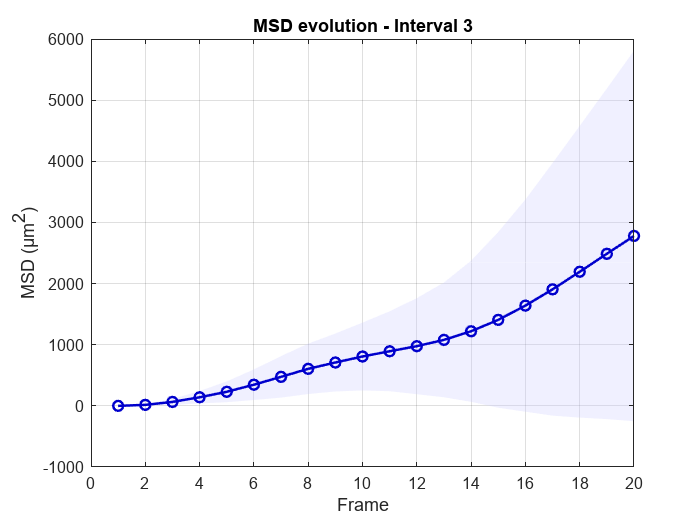

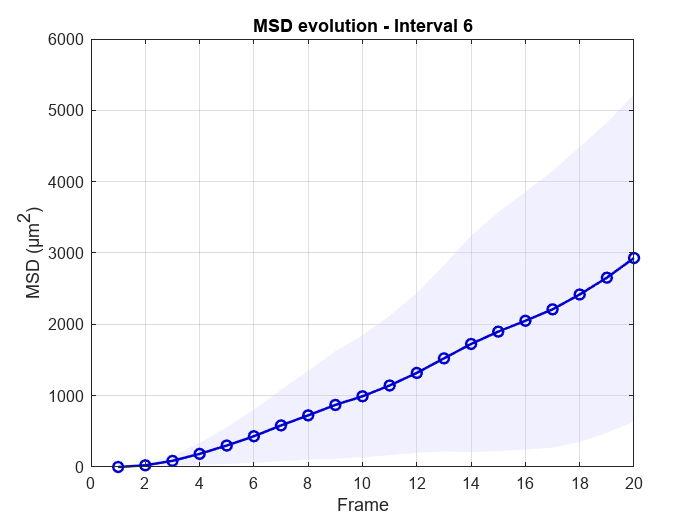



% Final table
intervals = (1:num_intervals)';
Tfinal = table(intervals, msd_mean_per_interval', msd_std_per_interval', ...
    'VariableNames', {'Interval', 'MSD_Mean', 'MSD_Std'});
% writetable(Tfinal, 'msd_mean_per_interval_with_error.xlsx');


interval_times_s = zeros(num_intervals, 1);
for k = 1:num_intervals
    start_frame = (k - 1) * frame_intervals + 1;
    idx = find(converted_data.FRAME_SOURCE == start_frame, 1, 'first');
    if ~isempty(idx)
        interval_times_s(k) = converted_data.POSITION_T_SOURCE(idx);
    else
        interval_times_s(k) = NaN;
    end
end
% === PLOT MSD mean PER INTERVAL ===

h1 = figure('Name','MSDmean');
fill([intervals', fliplr(intervals')], ...
     [msd_mean_per_interval + msd_std_per_interval, fliplr(msd_mean_per_interval - msd_std_per_interval)], ...
     [0.8 0.8 1], 'EdgeColor', 'none', 'FaceAlpha', 0.3);
hold on;
plot(intervals, msd_mean_per_interval, '-o', 'LineWidth', 1.5, 'MarkerSize', 6, 'Color', [0 0 0.8]);
xlabel('Interval');
ylabel('MSD average (\mum^2)');
title('MSD Average for Interval with error');
grid on;

ax1 = gca;


tick_idx = ax1.XTick;
tick_idx = tick_idx(tick_idx>=1 & tick_idx<=numel(interval_times_s));
sec_labels = strings(size(tick_idx));
for i=1:length(tick_idx)
    val = interval_times_s(round(tick_idx(i)));
    if ~isnan(val)
        sec_labels(i) = sprintf('%.1f', val);
    else
        sec_labels(i) = "";
    end
end

ax1_pos = ax1.Position;
% ax2 = axes('Position', ax1_pos, ...
%            'XAxisLocation','top', ...
%            'YAxisLocation','right', ...
%            'Color','none', ...
%            'XColor','k', ...
%            'YColor','none', ...
%            'Box','off');
% 
% set(ax2, 'XLim', ax1.XLim, ...
%          'XTick', tick_idx, ...
%          'XTickLabel', sec_labels, ...
%          'XLabel', text(0.5,1.07,'Time [s]','Units','normalized','HorizontalAlignment','center','FontWeight','bold','Parent',ax2));
% 
% ax2.XAxis.TickLength = [0 0]; 
% linkaxes([ax1 ax2],'x')       

axes(ax1); 

% --- DRAW FLASH AREAS---
flash_intervals = ceil(flash_intervals_frames / frame_intervals); %  frame → interval

draw_flash_areas(flash_intervals);

hold off;
% === PLOT MSD CURVE ALL INTERVALS ===
h2=figure('Name','MSDevolution');
hold on;
frames = 1:frame_intervals;
cmap = parula(num_intervals);
for i = 1:num_intervals
    if ~isempty(msd_evolutions{i})
        plot(frames, msd_evolutions{i}, 'LineWidth', 1.5, 'Color', cmap(i,:));
    end
end
colormap(cmap);
cb = colorbar;
cb.Ticks = linspace(0,1,6);
cb.TickLabels = round(linspace(1,num_intervals,6));
cb.Label.String = 'Interval';
xlabel('Frame in Interval');
ylabel('MSD (µm^2)');
title('MSD curves for all intervals (colormap)');
grid on;
hold off;

% === PLOT MSD CURVE NORM ===
h3=figure('Name','MSDevolutionNorm');
hold on;
for i = 1:num_intervals
    if ~isempty(msd_evolutions{i}) && max(msd_evolutions{i}) > 0
        norm_curve = msd_evolutions{i}/max(msd_evolutions{i});
        plot(frames, norm_curve, 'LineWidth', 1.2, 'Color', cmap(i,:));
    end
end
colormap(cmap);
cb = colorbar;
cb.Ticks = linspace(0,1,6);
cb.TickLabels = round(linspace(1,num_intervals,6));
cb.Label.String = 'Interval';
xlabel('Frame in Interval');
ylabel('MSD normalized');
title('Normalised MSD curves by interval(colormap)');
grid on;
hold off;

% === PLOT CURVE MSD WITH ERRORS OF SPECIFIC INTERVALS debug (e.g: 3, 6, 28) ===
for selected_interval = [3, 6, 28]
    if selected_interval <= num_intervals && ~isempty(msd_evolutions{selected_interval})
        msd_curve = msd_evolutions{selected_interval};
        msd_std_curve = msd_std_evolutions{selected_interval};
        frames = 1:length(msd_curve);
        figure;
        fill([frames, fliplr(frames)], ...
             [msd_curve + msd_std_curve, fliplr(msd_curve - msd_std_curve)], ...
             [0.8 0.8 1], 'EdgeColor', 'none', 'FaceAlpha', 0.3);
        hold on;
        plot(frames, msd_curve, '-o', 'LineWidth', 1.5, 'MarkerSize', 6, 'Color', [0 0 0.8]);
        xlabel('Frame');
        ylabel('MSD (µm^2)');
        title(sprintf('MSD evolution - Interval %d', selected_interval));
        grid on;
    end
end

% === Fitting models definition ===
msd_global = mean(cell2mat(msd_evolutions'),1,'omitnan');
fit_models = {
    'Linear',              'poly1',     [];
    'Quadratic',           'poly2',     [];
    'Cubic',               'poly3',     [];
    'Exponential',         'a*exp(b*x)', [max(msd_global), 0.05];
    'PowerLaw',           'a*x^b',     [max(msd_global), 1];
    'AnomDiff',         'a*(1-exp(-b*x))', [max(msd_global), 0.05];
     'OrnsteinUhlenbeck',   'L^2*(1 - exp(-x/tau_c))',   [max(msd_global), 1];
};
num_models = size(fit_models,1);

frame_vec = (1:frame_intervals)';

% === FIT for each interval (raw data and normalized on y axis only) ===
fit_results.interval = struct();
fit_results.interval_norm = struct();
for m = 1:num_models
    fit_results.interval.(fit_models{m,1}) = repmat(struct( ...
        'params', nan, ...
        'errs', nan, ...
        'param_names', {{}}, ...
        'r2', nan, ...
        'rmse', nan ...
    ), num_intervals, 1);
    fit_results.interval_norm.(fit_models{m,1}) = repmat(struct( ...
        'params', nan, ...
        'errs', nan, ...
        'param_names', {{}}, ...
        'r2', nan, ...
        'rmse', nan ...
    ), num_intervals, 1);
end

for interval_index = 1:num_intervals
    msd_curve = msd_evolutions{interval_index};
    if isempty(msd_curve) || all(isnan(msd_curve)), continue; end
    x = frame_vec;
    y = msd_curve(:);
    y_norm = y / max(y);

    for m = 1:num_models
        nome = fit_models{m,1};
        modello = fit_models{m,2};
        start = fit_models{m,3};
        % --- 
        try
            if contains(modello, 'poly')
                [f, gof] = fit(x, y, modello);
            else
                ft = fittype(modello, 'independent', 'x');
                [f, gof] = fit(x, y, ft, 'StartPoint', start);
            end
            ci = confint(f);
            par_names = coeffnames(f);
            coeffvals = cellfun(@(n) f.(n), par_names);
            coefferrs = (ci(2,:) - ci(1,:))/2;
            r2 = gof.rsquare;
            rmse = gof.rmse;
        catch
            par_names = {};
            coeffvals = nan;
            coefferrs = nan;
            r2 = nan;
            rmse = nan;
        end
        fit_results.interval.(nome)(interval_index) = struct(...
            'params', coeffvals, ...
            'errs', coefferrs, ...
            'param_names', {par_names}, ...
            'r2', r2, ...
            'rmse', rmse);

        % ---
        try
            if contains(modello, 'poly')
                [f, gof] = fit(x, y_norm, modello);
            else
                ft = fittype(modello, 'independent', 'x');
                start_norm = [1, 1];
                [f_norm, gof_norm] = fit(x, y_norm, ft, 'StartPoint', start_norm);
                %[f, gof] = fit(x, y_norm, ft, 'StartPoint', start);
            end
            ci = confint(f);
            par_names = coeffnames(f);
            coeffvals = cellfun(@(n) f.(n), par_names);
            coefferrs = (ci(2,:) - ci(1,:))/2;
            r2 = gof.rsquare;
            rmse = gof.rmse;
        catch
            par_names = {};
            coeffvals = nan;
            coefferrs = nan;
            r2 = nan;
            rmse = nan;
        end
        fit_results.interval_norm.(nome)(interval_index) = struct(...
            'params', coeffvals, ...
            'errs', coefferrs, ...
            'param_names', {par_names}, ...
            'r2', r2, ...
            'rmse', rmse);
    end
end

% === FIT on MSD global ===
x = frame_vec;
y = msd_global(:);

fit_results.global = struct();
fit_results.global_norm = struct();

for m = 1:num_models
    nome = fit_models{m,1};
    modello = fit_models{m,2};
    start = fit_models{m,3};
    % --- FIT raw ---
    try
        if contains(modello, 'poly')
            [f, gof] = fit(x, y, modello);
        else
            ft = fittype(modello, 'independent', 'x');
            [f, gof] = fit(x, y, ft, 'StartPoint', start);
        end
        ci = confint(f);
        par_names = coeffnames(f);
        coeffvals = cellfun(@(n) f.(n), par_names);
        coefferrs = (ci(2,:) - ci(1,:))/2;
        r2 = gof.rsquare;
        rmse = gof.rmse;
    catch
        par_names = {};
        coeffvals = nan;
        coefferrs = nan;
        r2 = nan;
        rmse = nan;
    end
    fit_results.global.(nome) = struct(...
        'params', coeffvals, ...
        'errs', coefferrs, ...
        'param_names', {par_names}, ...
        'r2', r2, ...
        'rmse', rmse);

    % --- FIT global Y nomr ---
    y_norm = y / max(y);
    try
        if contains(modello, 'poly')
            [f, gof] = fit(x, y_norm, modello);
        else
            ft = fittype(modello, 'independent', 'x');
            if strcmp(nome, 'PowerLaw')
                start_norm = [1, 1];
            else
                start_norm = start;
            end
        [f, gof] = fit(x, y_norm, ft, 'StartPoint', start_norm);
        end

        ci = confint(f);
        par_names = coeffnames(f);
        coeffvals = cellfun(@(n) f.(n), par_names);
        coefferrs = (ci(2,:) - ci(1,:))/2;
        r2 = gof.rsquare;
        rmse = gof.rmse;
    catch
        par_names = {};
        coeffvals = nan;
        coefferrs = nan;
        r2 = nan;
        rmse = nan;
    end
    fit_results.global_norm.(nome) = struct(...
        'params', coeffvals, ...
        'errs', coefferrs, ...
        'param_names', {par_names}, ...
        'r2', r2, ...
        'rmse', rmse);
end

save(fullfile(msd_path,'fit_results_struct.mat'),'fit_results');


% --- parameters
frames = (1:frame_intervals)';
maxPerFig = 7; % numbers of fit
n_fig = ceil(num_models / maxPerFig);

% --- models
eval_models = {
    @(b,x) b(1)*x + b(2);                           % poly1
    @(b,x) b(1)*x.^2 + b(2)*x + b(3);               % poly2
    @(b,x) b(1)*x.^3 + b(2)*x.^2 + b(3)*x + b(4);   % poly3
    @(b,x) b(1)*exp(b(2)*x);                        % Exponential
    @(b,x) b(1)*x.^b(2);                            % Powerlaw
    @(b,x) b(1)*(1 - exp(-b(2)*x));                 % DiffAnom
    @(b,x) b(1)^2 * (1 - exp(-x./b(2)));            % OU
};

model_labels = fit_models(:,1);

% === FIGURE 1: RAW DATA
for fig = 1:n_fig
    h4=figure('Name', 'DataFit');
    hold on;
    plot(frames, msd_global, 'ko-', 'LineWidth', 2, 'DisplayName', 'MSD mean');
    colors = lines(num_models);
    idx_start = (fig-1)*maxPerFig+1;
    idx_end = min(fig*maxPerFig, num_models);

    % --- Plot fit
    for m = idx_start:idx_end
        dati = fit_results.global.(model_labels{m});
        coeffs = dati.params;
        if all(isnan(coeffs)), continue; end
        yfit = eval_models{m}(coeffs, frames);
        plot(frames, yfit, '--', 'Color', colors(m,:), 'LineWidth', 1.5, ...
            'DisplayName', sprintf('%s (R2=%.3f)', model_labels{m}, dati.r2));
    end
    legend('show');
    xlabel('Frame');
    ylabel('MSD (\mum^2)');
    title(sprintf('Fit global MSD models (raw data)'));
    grid on;
       hold off;
    
end


% === FIGURE 2: Y NORM DATA ===
msd_global_norm = msd_global / max(msd_global);
for fig = 1:n_fig
     h41=figure('Name', 'DataFitNorm');
    hold on;
    plot(frames, msd_global_norm, 'ko-', 'LineWidth', 2, 'DisplayName', 'MSD mean norm');
    colors = lines(num_models);
    idx_start = (fig-1)*maxPerFig+1;
    idx_end = min(fig*maxPerFig, num_models);

    % --- Plot fit
    for m = idx_start:idx_end
        dati = fit_results.global_norm.(model_labels{m});
        coeffs = dati.params;
        if all(isnan(coeffs)), continue; end
        yfit = eval_models{m}(coeffs, frames);
        plot(frames, yfit, '--', 'Color', colors(m,:), 'LineWidth', 1.5, ...
            'DisplayName', sprintf('%s (R2=%.3f)', model_labels{m}, dati.r2));
    end
    legend('show');
    xlabel('Frame');
    ylabel('MSD normalized');

    title(sprintf('Fit global MSD models (normalized data)', fig, n_fig));
    grid on;
    hold off;
    
end

% === PRINT parameters and video of global MSD ===
fprintf('\n=== FIT PARAMETERS ON MSD global ===\n');


=== FIT PARAMETERS ON MSD global ===


for m = 1:num_models
    dati = fit_results.global.(model_labels{m});
    coeffs = dati.params;
    errs = dati.errs;
    par_names = dati.param_names;
    if all(isnan(coeffs)), continue; end
    fprintf('\n%s:\n', model_labels{m});
    for p = 1:length(par_names)
        fprintf('   %s = %.4g ± %.2g\n', par_names{p}, coeffs(p), errs(p));
    end
    fprintf('   R2 = %.4f, RMSE = %.4f\n', dati.r2, dati.rmse);
end

Linear:


   p1 = 271.1 ± 29
   p2 = -980.1 ± 3.5e+02


   R2 = 0.9558, RMSE = 354.5505


Quadratic:


   p1 = 11.31 ± 0.48
   p2 = 33.53 ± 10
   p3 = -108.9 ± 47


   R2 = 0.9997, RMSE = 30.0407


Cubic:


   p1 = -0.1811 ± 0.024
   p2 = 17.02 ± 0.75
   p3 = -15.57 ± 6.9
   p4 = -12.72 ± 17


   R2 = 1.0000, RMSE = 7.3659


Exponential:


   a = 312.9 ± 90
   b = 0.1429 ± 0.016


   R2 = 0.9720, RMSE = 282.0177


PowerLaw:


   a = 16.67 ± 1.5
   b = 1.91 ± 0.032


   R2 = 0.9996, RMSE = 35.1082


AnomDiff:


   a = 6.589e+06 ± 1.3e+10
   b = 3.025e-05 ± 0.061


   R2 = 0.8687, RMSE = 610.9138


OrnsteinUhlenbeck:


   L = 5854 ± 1.1e+07
   tau_c = 1.718e+05 ± 6.4e+08


   R2 = 0.8687, RMSE = 610.7901



fprintf('\n=== FIT PARAMETERS ON MSD global NORMALIZED ===\n');


=== FIT PARAMETERS ON MSD global NORMALIZED ===


for m = 1:num_models
    dati = fit_results.global_norm.(model_labels{m});
    coeffs = dati.params;
    errs = dati.errs;
    par_names = dati.param_names;
    if all(isnan(coeffs)), continue; end
    fprintf('\n%s (normalized):\n', model_labels{m});
    for p = 1:length(par_names)
        fprintf('   %s = %.4g ± %.2g\n', par_names{p}, coeffs(p), errs(p));
    end
    fprintf('   R2 = %.4f, RMSE = %.4f\n', dati.r2, dati.rmse);
end

Linear (normalized):


   p1 = 0.0537 ± 0.0057
   p2 = -0.1941 ± 0.069


   R2 = 0.9558, RMSE = 0.0702


Quadratic (normalized):


   p1 = 0.002241 ± 9.5e-05
   p2 = 0.006641 ± 0.002
   p3 = -0.02157 ± 0.0093


   R2 = 0.9997, RMSE = 0.0059


Cubic (normalized):


   p1 = -3.587e-05 ± 4.7e-06
   p2 = 0.00337 ± 0.00015
   p3 = -0.003083 ± 0.0014
   p4 = -0.002518 ± 0.0034


   R2 = 1.0000, RMSE = 0.0015


Exponential (normalized):


   a = -8.824 ± 1.2e+08
   b = -9.252 ± 1.3e+07


   R2 = -1.3626, RMSE = 0.5131


PowerLaw (normalized):


   a = 6.816e-05 ± 1.1
   b = -3.733 ± 2.8e+05


   R2 = -1.3626, RMSE = 0.5131


AnomDiff (normalized):


   a = 5409 ± 4.5e+07
   b = 7.301e-06 ± 0.061


   R2 = 0.8687, RMSE = 0.1210


OrnsteinUhlenbeck (normalized):


   L = 56.05 ± 1.1e+05
   tau_c = 7.954e+04 ± 3e+08


   R2 = 0.8687, RMSE = 0.1210


%% ===  param_struct with debug failure fitting
param_struct = struct();

for m = 1:num_models
    nome = fit_models{m,1};

    % numbers of model parameters
    param_names = fit_results.interval.(nome)(1).param_names;
    npar = numel(param_names);

    
    param_struct.(nome).params = nan(num_intervals, npar);
    param_struct.(nome).errs  = nan(num_intervals, npar);
    param_struct.(nome).r2    = nan(num_intervals, 1);
    param_struct.(nome).rmse  = nan(num_intervals, 1);

    
    for k = 1:num_intervals
        fit_k = fit_results.interval.(nome)(k);

        
        fit_failed = isempty(fit_k.params) || numel(fit_k.params) ~= npar;

        if ~fit_failed
            param_struct.(nome).params(k,:) = fit_k.params(:)';
            param_struct.(nome).errs(k,:)   = fit_k.errs(:)';
            param_struct.(nome).r2(k)       = fit_k.r2;
            param_struct.(nome).rmse(k)     = fit_k.rmse;
        else
            % NaN ( prealloc) 
            param_struct.(nome).r2(k)   = NaN;
            param_struct.(nome).rmse(k) = NaN;
        end
    end

    param_struct.(nome).param_names = param_names;
end


% === 2. EXPORT ON EXCEL (.xlsx) ===
outfilename = fullfile(msd_path,'fit_parameters_models.xlsx');
for m = 1:num_models
    nome = fit_models{m,1};
    npar = length(param_struct.(nome).param_names);
    par_names = param_struct.(nome).param_names;
    intervalli = (1:num_intervals)';
    
    T = table(intervalli, ...
        param_struct.(nome).r2, ...
        param_struct.(nome).rmse, ...
        'VariableNames', {'Interval','R2','RMSE'});
    
    for p = 1:npar
        T.(['param_' par_names{p}]) = param_struct.(nome).params(:,p);
        T.(['err_' par_names{p}])   = param_struct.(nome).errs(:,p);
    end
    % Export
    writetable(T, outfilename, 'Sheet', nome(1:min(31,end)));
end

% === 3. Auto CLASSIFY OF BEST FITTINGs (always Linear, Powerlaw + 2 extra) ===
meanR2 = zeros(num_models,1);
for m = 1:num_models
    nome = fit_models{m,1};
    meanR2(m) = nanmean(param_struct.(nome).r2);
end

idx_linear = find(strcmp(fit_models(:,1), 'Linear'));
idx_powerlaw = find(strcmp(fit_models(:,1), 'PowerLaw'));
mask = true(num_models,1); mask([idx_linear, idx_powerlaw]) = false;
[~, idxSort] = sort(meanR2(mask), 'descend');
idx_rest = find(mask);
idx_top = idx_rest(idxSort(1:2)); 
idx_plot = [idx_linear; idx_powerlaw; idx_top(:)];
modelli_plot = fit_models(idx_plot,1);

fprintf('Auto-selected models for plotting:\n');

Auto-selected models for plotting:


disp(modelli_plot);

    {'Linear'   }
    {'PowerLaw' }
    {'Cubic'    }
    {'Quadratic'}




% === 4. PLOT: 4 figures (1 for each model), parameters subplot ===
frames_intervals = (1:num_intervals)';
model_struct_name = @(s) matlab.lang.makeValidName(s); 

for mm = 1:length(idx_plot)
    nome = modelli_plot{mm};
    fieldname = model_struct_name(nome);

   
    all_param_names = param_struct.(fieldname).param_names;
    valid_idx = find(~cellfun(@isempty, all_param_names));
    param_names = all_param_names(valid_idx);
    npar = numel(param_names);

   
    h51=figure('Name', sprintf('Fit parameters - %s', nome), 'Color', 'w');
    for p = 1:npar
        subplot(npar, 1, p);
        x = frames_intervals;
        y = param_struct.(fieldname).params(:, valid_idx(p)); 
        e = param_struct.(fieldname).errs(:, valid_idx(p));   
        hold on;
        col = lines(1);

        
        fill([x; flipud(x)], [y+e; flipud(y-e)], col, ...
            'FaceAlpha', 0.3, 'EdgeColor', 'none');
        
        plot(x, y, '-', 'Color', col, 'LineWidth', 2);
        plot(x, y, 'o', 'Color', col, 'MarkerFaceColor', col);

        
        flash_intervals = ceil(flash_intervals_frames / frame_intervals); % frame → interval
        draw_flash_areas(flash_intervals);

        ylabel(param_names{p}, 'Interpreter', 'none');
        grid on;
        if p == 1
            title(sprintf('Fit parameters - Model: %s', nome), 'FontWeight', 'bold');
        end
        if p == npar
            xlabel('Interval');
        end

        
        ylimit = ylim;
        ypos = ylimit(2) + 0.06*(ylimit(2)-ylimit(1));
        tick_idx = get(gca,'XTick');
        tick_idx = tick_idx(tick_idx>=1 & tick_idx<=numel(interval_times_s));
        sec_labels = strings(size(tick_idx));
        for i=1:length(tick_idx)
            val = interval_times_s(round(tick_idx(i)));
            if ~isnan(val)
                sec_labels(i) = sprintf('%.1f', val);
            else
                sec_labels(i) = "";
            end
        end
        for i = 1:length(tick_idx)
            if strlength(sec_labels(i)) > 0
                text(tick_idx(i), ypos, sec_labels(i), ...
                    'HorizontalAlignment', 'center', ...
                    'VerticalAlignment', 'bottom', ...
                    'FontWeight', 'bold', ...
                    'Color', [0.1 0.1 0.1], ...
                    'FontSize', 9, ...
                    'Clipping', 'on');
            end
        end
        if p == 1
            text(mean(xlim), ylimit(2) + 0.12*(ylimit(2)-ylimit(1)), 'Time [s]', ...
                'HorizontalAlignment', 'center', ...
                'VerticalAlignment', 'bottom', ...
                'FontWeight', 'bold', ...
                'FontSize', 10, ...
                'Clipping', 'on');
        end
        hold off;
    end
    
    savefig(h51, fullfile(msd_path, sprintf('FitParams_%s.fig', nome)));  % formato MATLAB
    exportgraphics(h51, fullfile(msd_path, sprintf('FitParams_%s.png', nome)), 'Resolution', 300); % PNG ad alta risoluzione
end

% === 5. PLOT: R2 
h5=figure('Name', 'R2 of selected models', 'Color', 'w');
hold on;
cmap = lines(length(idx_plot));
for mm = 1:length(idx_plot)
    nome = modelli_plot{mm};
    plot(frames_intervals, param_struct.(nome).r2, '-', ...
        'LineWidth', 2, 'Color', cmap(mm,:), 'DisplayName', nome);
    plot(frames_intervals, param_struct.(nome).r2, 'o', ...
        'MarkerFaceColor', cmap(mm,:), 'MarkerEdgeColor', cmap(mm,:));
end
xlabel('Interval');
ylabel('R2');
legend('show', 'Location', 'best');
title('R2 of selected models', 'FontWeight', 'bold');
ylim([0.9 1.05]);
grid on;


save(fullfile(msd_path,'param_struct.mat'),'param_struct');


% === BOXPLOT 
h6=figure('Name','MSDintervalDistribution','Color','w');
hold on;
for interval_index = 1:num_intervals
    if exist('msd_per_alga_all','var') && ~isempty(msd_per_alga_all{interval_index})
        finale = msd_per_alga_all{interval_index}(:,end); 
        boxchart(ones(size(finale))*interval_index, finale, 'BoxFaceAlpha',0.5);
    end
end
xlabel('Interval');
ylabel('Final MSD per trace');
title('Final MSD distribution (boxplot) per interval');
grid on;
hold off;

% per usare la funzione flash
% hold on;
% draw_flash_areas(flash_intervals_frames);
% hold off;
% hold on;
% draw_flash_areas(flash_intervals_times);
% hold off;
% flash_intervals = ceil(flash_intervals_frames / frame_intervals); % frame → Interval
% hold on;
% draw_flash_areas(flash_intervals);
% hold off;

savefig(h1, fullfile(msd_path, 'MSDmean.fig'));
savefig(h2, fullfile(msd_path, 'MSDevolution.fig'));
savefig(h3, fullfile(msd_path, 'MSDevolutionNorm.fig'));
savefig(h4, fullfile(msd_path, 'DataFit.fig'));
savefig(h41, fullfile(msd_path, 'DataFitNorm'));
savefig(h5, fullfile(msd_path, ['FitParams_' nome '.fig']));
%savefig(h51, fullfile(msd_path, ['FitParams_' nome '.fig']));
savefig(h6, fullfile(msd_path, 'MSDintervalDistribution.fig'));


file_name = 'msd_complete_analysis.xlsx';

%% === sheet 1: MSD mean per interval with error and time===
T1 = table((1:num_intervals)', msd_mean_per_interval', msd_std_per_interval', interval_times_s, ...
    'VariableNames', {'Interval', 'MSD_Mean', 'MSD_Std', 'Time_s'});
writetable(T1, fullfile(msd_path,file_name), 'Sheet', 'MSD_Mean');

%% === sheet 2: MSD mean norm with error and time ===
msd_mean_per_interval_norm = msd_mean_per_interval / max(msd_mean_per_interval);
msd_std_per_interval_norm = msd_std_per_interval / max(msd_mean_per_interval);
T2 = table((1:num_intervals)', msd_mean_per_interval_norm', msd_std_per_interval_norm', interval_times_s, ...
    'VariableNames', {'Interval', 'MSD_Mean_Norm', 'MSD_Std_Norm', 'Time_s'});
writetable(T2, fullfile(msd_path, file_name), 'Sheet', 'MSD_Mean_Norm');

%% === sheet 3: models parameters per interval ===
colnames = {'Interval', 'Time_s'};
for m = 1:num_models
    nome = fit_models{m,1};
    npar = length(param_struct.(nome).param_names);
    for p = 1:npar
        par = param_struct.(nome).param_names{p};
        colnames{end+1} = [nome '_param_' par];
        colnames{end+1} = [nome '_err_' par];
    end
    colnames{end+1} = [nome '_R2'];
    colnames{end+1} = [nome '_RMSE'];
end

N = num_intervals;
M = length(colnames);
data_mat = nan(N, M);

data_mat(:,1) = (1:N)';           % Interval
data_mat(:,2) = interval_times_s; % Time

col_idx = 3;
for m = 1:num_models
    nome = fit_models{m,1};
    npar = length(param_struct.(nome).param_names);
    for p = 1:npar
        data_mat(:,col_idx)   = param_struct.(nome).params(:,p);
        col_idx = col_idx + 1;
        data_mat(:,col_idx)   = param_struct.(nome).errs(:,p);
        col_idx = col_idx + 1;
    end
    data_mat(:,col_idx)   = param_struct.(nome).r2;
    col_idx = col_idx + 1;
    data_mat(:,col_idx)   = param_struct.(nome).rmse;
    col_idx = col_idx + 1;
end

Twide = array2table(data_mat, 'VariableNames', colnames);
writetable(Twide, fullfile(msd_path, file_name), 'Sheet', 'Fit_Parameters_WIDE');

%% === sheet 4: Data for boxplot MSD ===
boxplot_data = [];
for interval_index = 1:num_intervals
    if ~isempty(msd_per_alga_all{interval_index})
        finale = msd_per_alga_all{interval_index}(:,end); 
        ntracce = numel(finale);
        tabella_box = table(repmat(interval_index,ntracce,1), repmat(interval_times_s(interval_index), ntracce,1), finale, ...
            'VariableNames', {'Interval', 'Time_s', 'Final_MSD'});
        boxplot_data = [boxplot_data; tabella_box];
    end
end
writetable(boxplot_data, fullfile(msd_path, file_name), 'Sheet', 'Boxplot_Data');

%% === sheet 5: colormap ===
msd_curve_all = [];

for interval_index = 1:num_intervals

if isempty(msd_evolutions{interval_index})
    msd_vals = nan(frame_intervals,1);
    msd_std_vals = nan(frame_intervals,1);
else
    msd_vals = msd_evolutions{interval_index}(:);
    msd_std_vals = msd_std_evolutions{interval_index}(:);
end
   
    N = length(msd_vals);

    frames = (1:N)';
    msd_mean = msd_vals;
    msd_std = msd_std_vals;
    msd_se = msd_std_vals ./ sqrt(N);

    interval_col = repmat(interval_index, N, 1);
    time_col = repmat(interval_times_s(interval_index), N, 1);

    tab = table(interval_col, frames, time_col, msd_mean, msd_std, msd_se, ...
        'VariableNames', {'Interval', 'Frame', 'Time_s', 'MSD_Mean', 'MSD_Std', 'MSD_SE'});

    msd_curve_all = [msd_curve_all; tab];
end

writetable(msd_curve_all, fullfile(msd_path, file_name), 'Sheet', 'MSD_Curves_AllIntervals');

% %% === sheet 6: MSD global per frame ===
% % non viene escono solo i primi frame
% frame_vec = (1:frame_intervals)';
% msd_global = mean(cell2mat(msd_evolutions'),1,'omitnan');
% msd_global_std = std(cell2mat(msd_evolutions'),0,1,'omitnan');
% msd_global_se = msd_global_std ./ sqrt(num_intervals);
% 
% Tglobal = table(frame_vec, msd_global', msd_global_std', msd_global_se', ...
%     'VariableNames', {'Frame', 'MSD_GlobalMean', 'MSD_GlobalStd', 'MSD_GlobalSE'});
% writetable(Tglobal, fullfile(msd_path, file_name), 'Sheet', 'MSD_GlobalCurve');

%% === sheet 7: fit parameters global ===
param_global = [];
for m = 1:num_models
    nome = fit_models{m,1};
    dati = fit_results.global.(nome);
    npar = length(dati.param_names);
    for p = 1:npar
        param_global = [param_global; {nome, dati.param_names{p}, dati.params(p), dati.errs(p), dati.r2, dati.rmse}];
    end
end
Tparam_global = cell2table(param_global, ...
    'VariableNames', {'Model', 'Parameter', 'Value', 'Error', 'R2', 'RMSE'});
writetable(Tparam_global, fullfile(msd_path, file_name), 'Sheet', 'Fit_Parameters_Global');

disp('Export complete! File: msd_complete_analysis.xlsx with all data for graphs.');

Export complete! File: msd_complete_analysis.xlsx with all data for graphs.



exportgraphics(h1, fullfile(msd_path,'MSDmean.png'), 'Resolution', 300);
exportgraphics(h2, fullfile(msd_path,'MSDevolution.png'), 'Resolution', 300);
exportgraphics(h3, fullfile(msd_path,'MSDevolutionNorm.png'), 'Resolution', 300);
exportgraphics(h4, fullfile(msd_path,'DataFit.png'), 'Resolution', 300);
exportgraphics(h41, fullfile(msd_path,'DataFitNorm.png'), 'Resolution', 300);
exportgraphics(h5, fullfile(msd_path,['FitParams_' nome '.png']), 'Resolution', 300);
exportgraphics(h6, fullfile(msd_path,'MSDintervalDistribution.png'), 'Resolution', 300);

if ~exist(msd_path,'dir'), mkdir(msd_path); end

% data MSD
save(fullfile(msd_path, 'msd_curve_all.mat'), 'msd_curve_all', '-v7.3');
save(fullfile(msd_path, 'msd_evolutions.mat'), 'msd_evolutions', '-v7.3');

% tables for intervals
save(fullfile(msd_path, 'msd_ave.mat'), 'T1');      % T1
save(fullfile(msd_path, 'msd_ave_norm.mat'), 'T2'); % T2

% data per-track 
save(fullfile(msd_path, 'msd_per_alga_all.mat'), 'msd_per_alga_all', '-v7.3');

save(fullfile(msd_path,'msd_global.mat'),'msd_global');
save(fullfile(msd_path,'msd_global_norm.mat'),'msd_global_norm');
save(fullfile(msd_path,'fit_results.mat'),'fit_results','-v7.3');             
save(fullfile(msd_path,'interval_times_s.mat'),'interval_times_s');           
% (Alternative option B: Save the field directly as a PowerLaw variable)
% save(fullfile(msd_path, 'powerLaw_struct_alt.mat'), '-struct', 'param_struct', 'PowerLaw');


        close all;          % free memory 
        java.lang.System.gc 

else
    disp(['File converted_data not found: ', video_path]);
end

    end
    java.lang.System.gc

end

